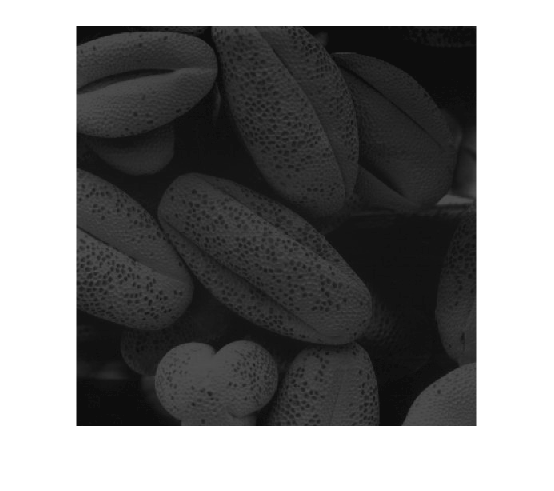

load Q3\original_img.mat;
source=imread("Q3\source.jpg");
target=imread("Q3\target.jpg");
imshow(original_img);

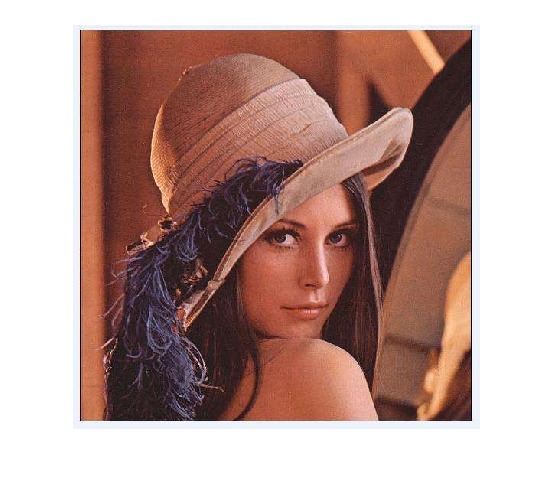

imshow(source);

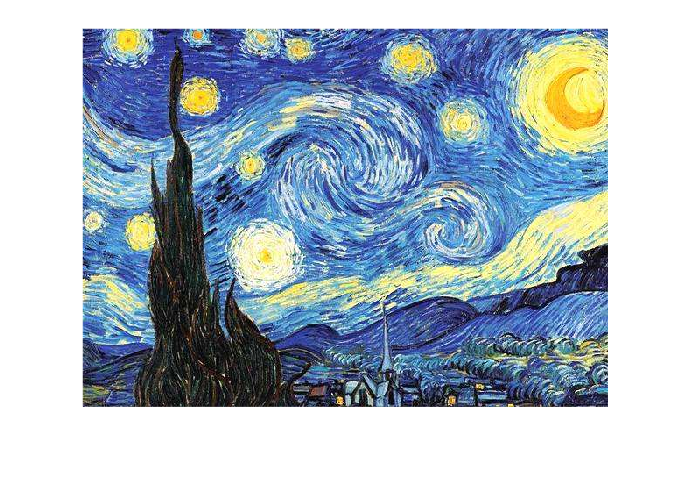

imshow(target);

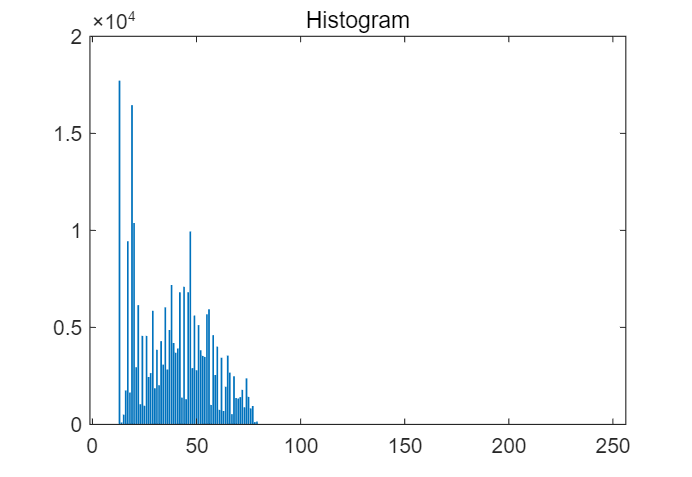



%help imhist
%[counts,binLocations]=imhist(original_img);
%bar(binLocations,counts);

[n,m]=size(original_img);
cnt=zeros(256,1);
bin=zeros(256,1);
for i=[1:256]
    bin(i,1)=i-1;
end
for i=[1:n]
    for j=[1:m]
        cnt(original_img(i,j)+1,1)=cnt(original_img(i,j)+1,1)+1;
    end
end
bar(bin,cnt);title("Histogram");

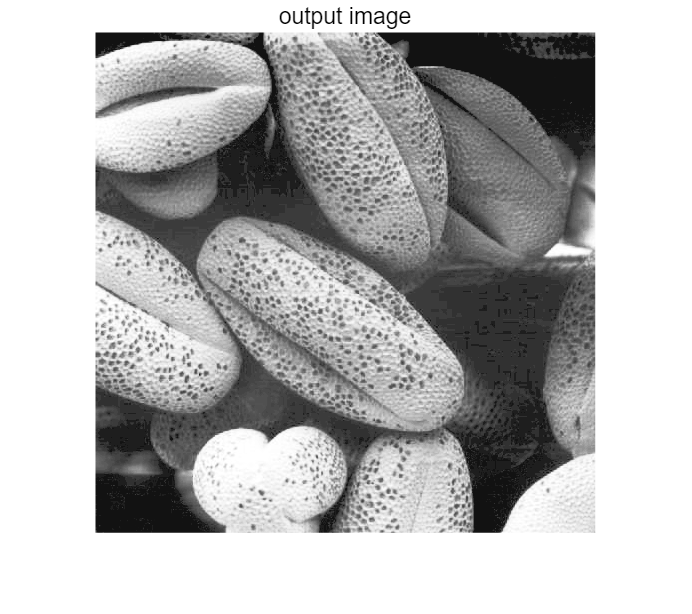



%cnt=imhist(original_img)
p=cnt/(n*m);
p=cumsum(p);
p=p*255;
p=round(p);
output=uint8(zeros(n,m));
for i=[1:n]
    for j=[1:m]
        output(i,j)=p(original_img(i,j)+1,1);
    end
end
imshow(output);title("output image");

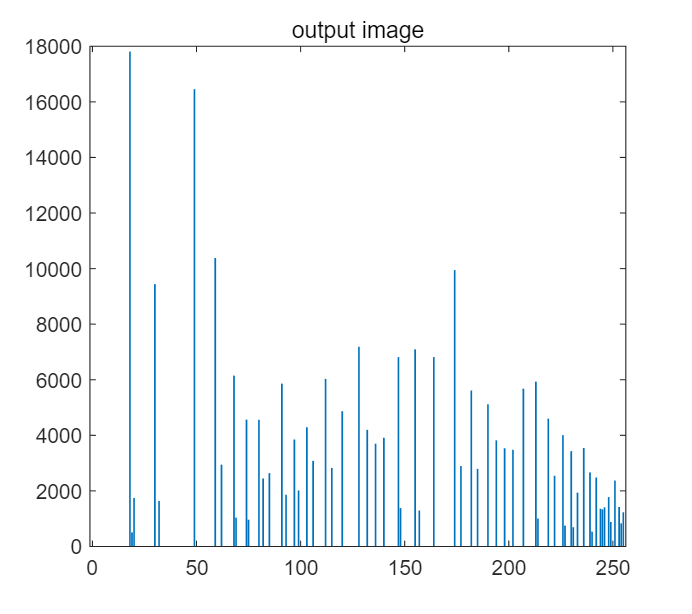

[counts,binLocations]=imhist(output);
bar(binLocations,counts);title("output image");


%x=histeq(original_img);
%imshow(x);
%[counts,binLocations]=imhist(x);
%bar(binLocations,counts);

%help histogram
%histogram(original_img);
%help bar
%help histeq
%p

[source_n,source_m,dim]=size(source);
[target_n,target_m,dim]=size(target);
x=uint8(zeros(source_n,source_m,3));
for k=[1:3]
    source_x=source(:,:,k);%获取原图像k通道
    source_hist=imhist(source_x);%获取原图像k通道直方图
    target_x=target(:,:,k);%获取匹配图像k通道
    target_hist=imhist(target_x);%获取匹配图像k通道直方图
    %x(:,:,k)=histeq(source_x,target_hist);%R通道直方图匹配,系统自带,可惜不让用
    source_p=cumsum(source_hist)/(source_n*source_m);
    target_p=cumsum(target_hist)/(target_n*target_m);
    map=zeros(1,256);%从0到255分别的映射
    help min
    for i=[1:256]
        [val,pos]=min(abs(source_p(i)-target_p));%找到target_p中与source(i)最接近的位置
        map(i)=pos-1;
    end
    x(:,:,k)=map(double(source_x)+1);
end

 min - 数组的最小元素
    此 MATLAB 函数 返回数组的最小元素。 如果 A 是向量，则 min(A) 返回 A 的最小值。 如果
    A 为矩阵，则 min(A) 是包含每一列的最小值的行向量。 如果 A 是多维数组，则 min(A) 沿
    大小不等于 1 的第一个数组维度计算，并将这些元素视为向量。此维度的大小将变为 1，而所有其
    他维度的大小保持不变。如果 A 是第一个维度为 0 的空数组，则 min(A) 返回与 A 大小相同
    的空数组。

    M = min(A)
    M = min(A,[],dim)
    M = min(A,[],nanflag)
    M = min(A,[],dim,nanflag)
    [M,I] = min(___)

    M = min(A,[],'all')
    M = min(A,[],vecdim)
    M = min(A,[],'all',nanflag)
    M = min(A,[],vecdim,nanflag)

    [M,I] = min(A,[],___,'linear')

    C = min(A,B)
    C = min(A,B,nanflag)

    See also <a href="D:\matlab\help\matlab\ref\mink.html">mink</a>, <a href="D:\matlab\help\matlab\ref\bounds.html">bounds</a>, <a href="D:\matlab\help\matlab\ref\max.html">max</a>, <a href="D:\matlab\help\matlab\ref\mean

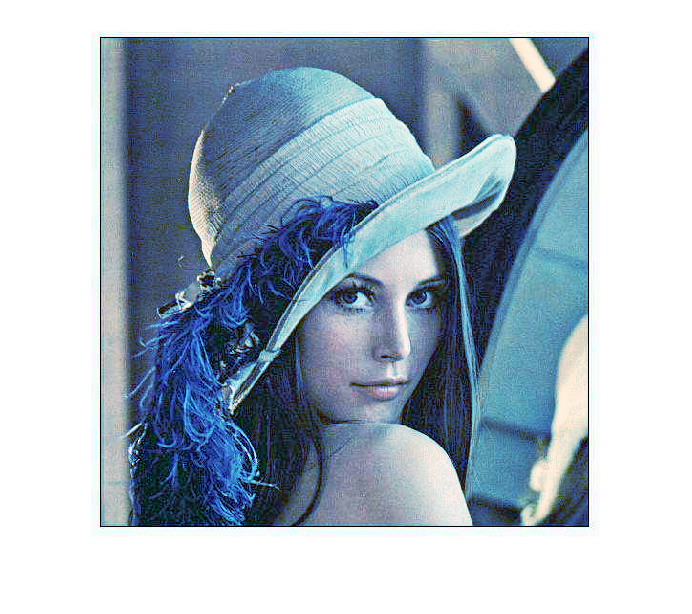

result=cat(3,x(:,:,1),x(:,:,2),x(:,:,3));
imshow(result);

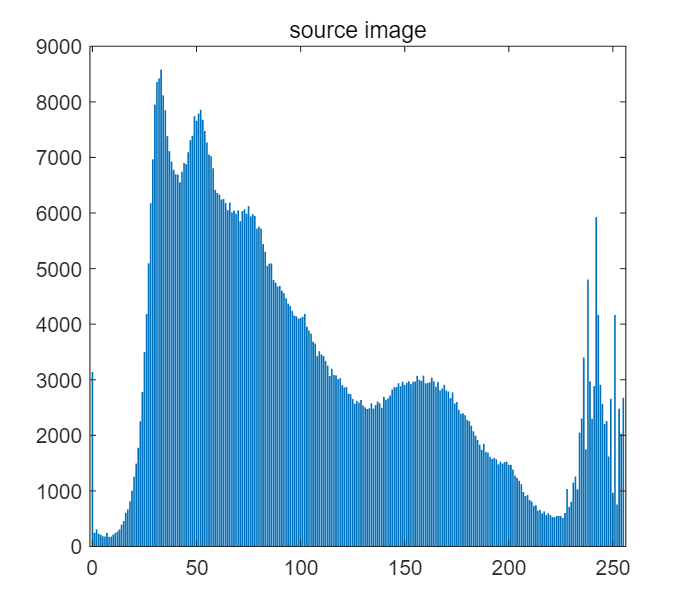


[counts,binLocations]=imhist(source);
bar(binLocations,counts);title("source image");

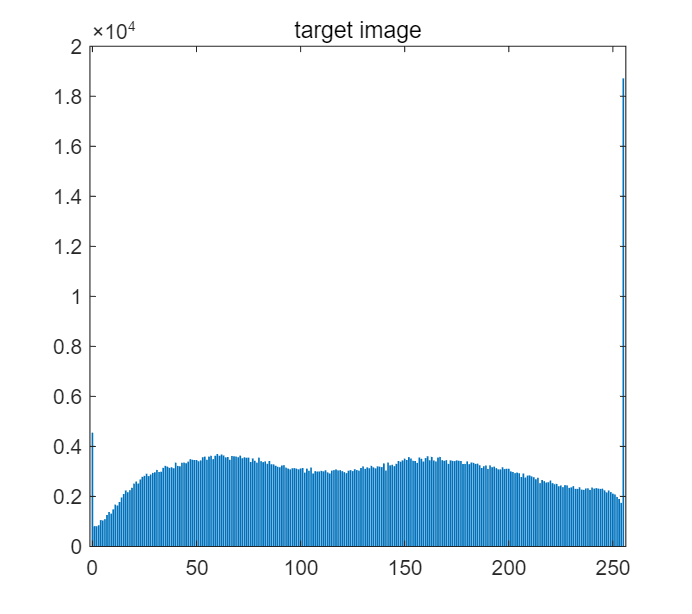

[counts,binLocations]=imhist(target);
bar(binLocations,counts);title("target image");

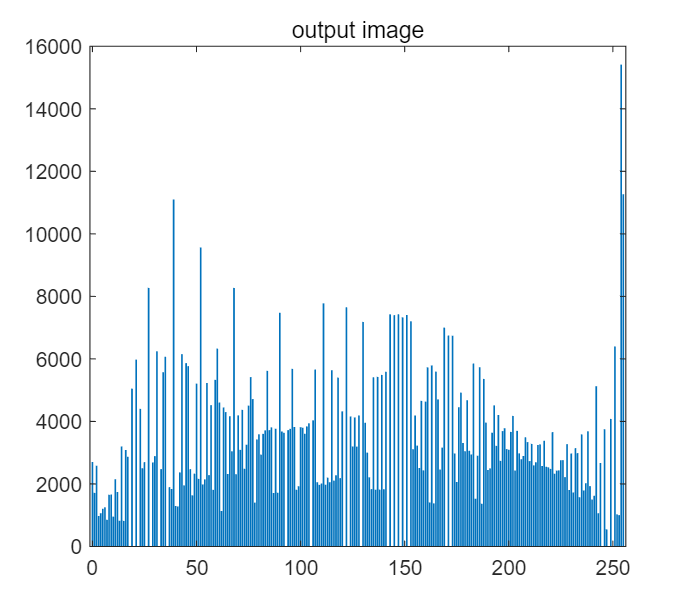

[counts,binLocations]=imhist(result);
bar(binLocations,counts);title("output image");


help histeq

 histeq - 使用直方图均衡增强对比度
    此 MATLAB 函数 变换灰度图像 I，以使输出灰度图像 J 具有 length(hgram) 个 bin 的直
    方图近似匹配目标直方图 hgram。

    J = histeq(I,hgram)
    J = histeq(I,n)
    J = histeq(I)

    newmap = histeq(X,map)
    newmap = histeq(X,map,hgram)

    [___,T] = histeq(___)

    See also <a href="D:\matlab\help\images\ref\adapthisteq.html">adapthisteq</a>, <a href="D:\matlab\help\images\ref\../../matlab/ref/brighten.html">brighten</a>, <a href="D:\matlab\help\images\ref\imadjust.html">imadjust</a>, <a href="D:\matlab\help\images\ref\imhist.html">imhist</a>

    histeq 的文档
    名为 histeq 的其他函数

